Se utilizará el DigitDataset para el entrenamiento de las redes

- Resnet-50 (Cerca de 23 millones de parámetros entrenables)

- LeNet (Google) (Cerca de 6.79 millones de parámetros entrenables)

Este dataset contiene imágenes de los dígitos escritos a mano del 0 al 9 para poder hacer una clasificación de los mismos mediante una imagen.

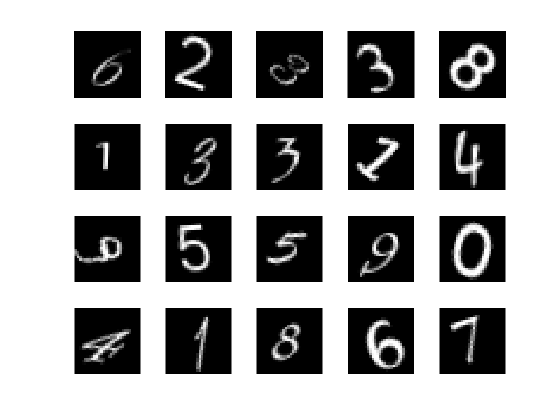

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

# **ResNet - 50**

Para esta serie de experimentos lo que se variará es la tasa de aprendizaje y el batch size junto con el número de épocas, para ver qué tanto varía.

Lo primero que se hará es utilizar la red pre entrenada ResNet-50, la arquitectura de esta hace uso de algo llamado "Bloque residual" el cual ataca directamente el problema del gradiente evanescente de la siguiente manera:

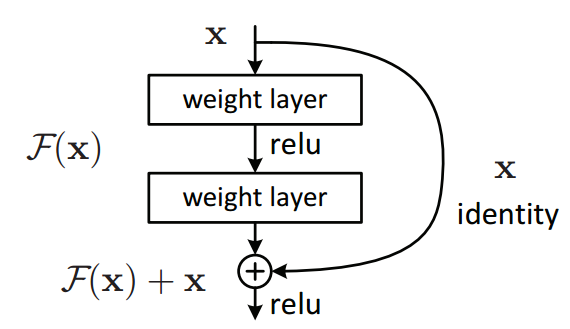

Al computarse la función de activación de una capa anterior, se hace una conexión directa de la salida de esa capa a un sumador que tendrá en cuenta la salida de 1 o más capas más adelante, a esto también se le llama Skip connections ya que se veía el problema de que al aumentar la cantidad de capas, el gradiente iba desvaneciéndose a medida de que pasaba hacia atrás.

Otra de los beneficios de usar Skip Connections es que ayuda con el overfitting.

Para el primer entrenamiento se tomará un BatchSize de 100, un LR de 0.001 inicial y se hará con optimizador Adam, además de esto se hará la validación por cada iteración, el entrenamiento se hace con la configuración de la imagen siguiente:

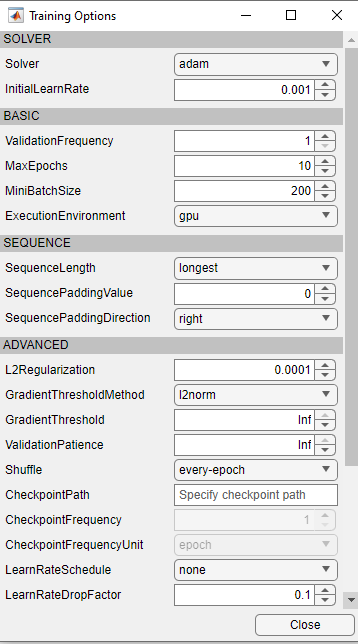

En un resultado intermedio del entrenamiento con 6 épocas se ve que la red ya se quedó estancada en ese punto desde la época 1

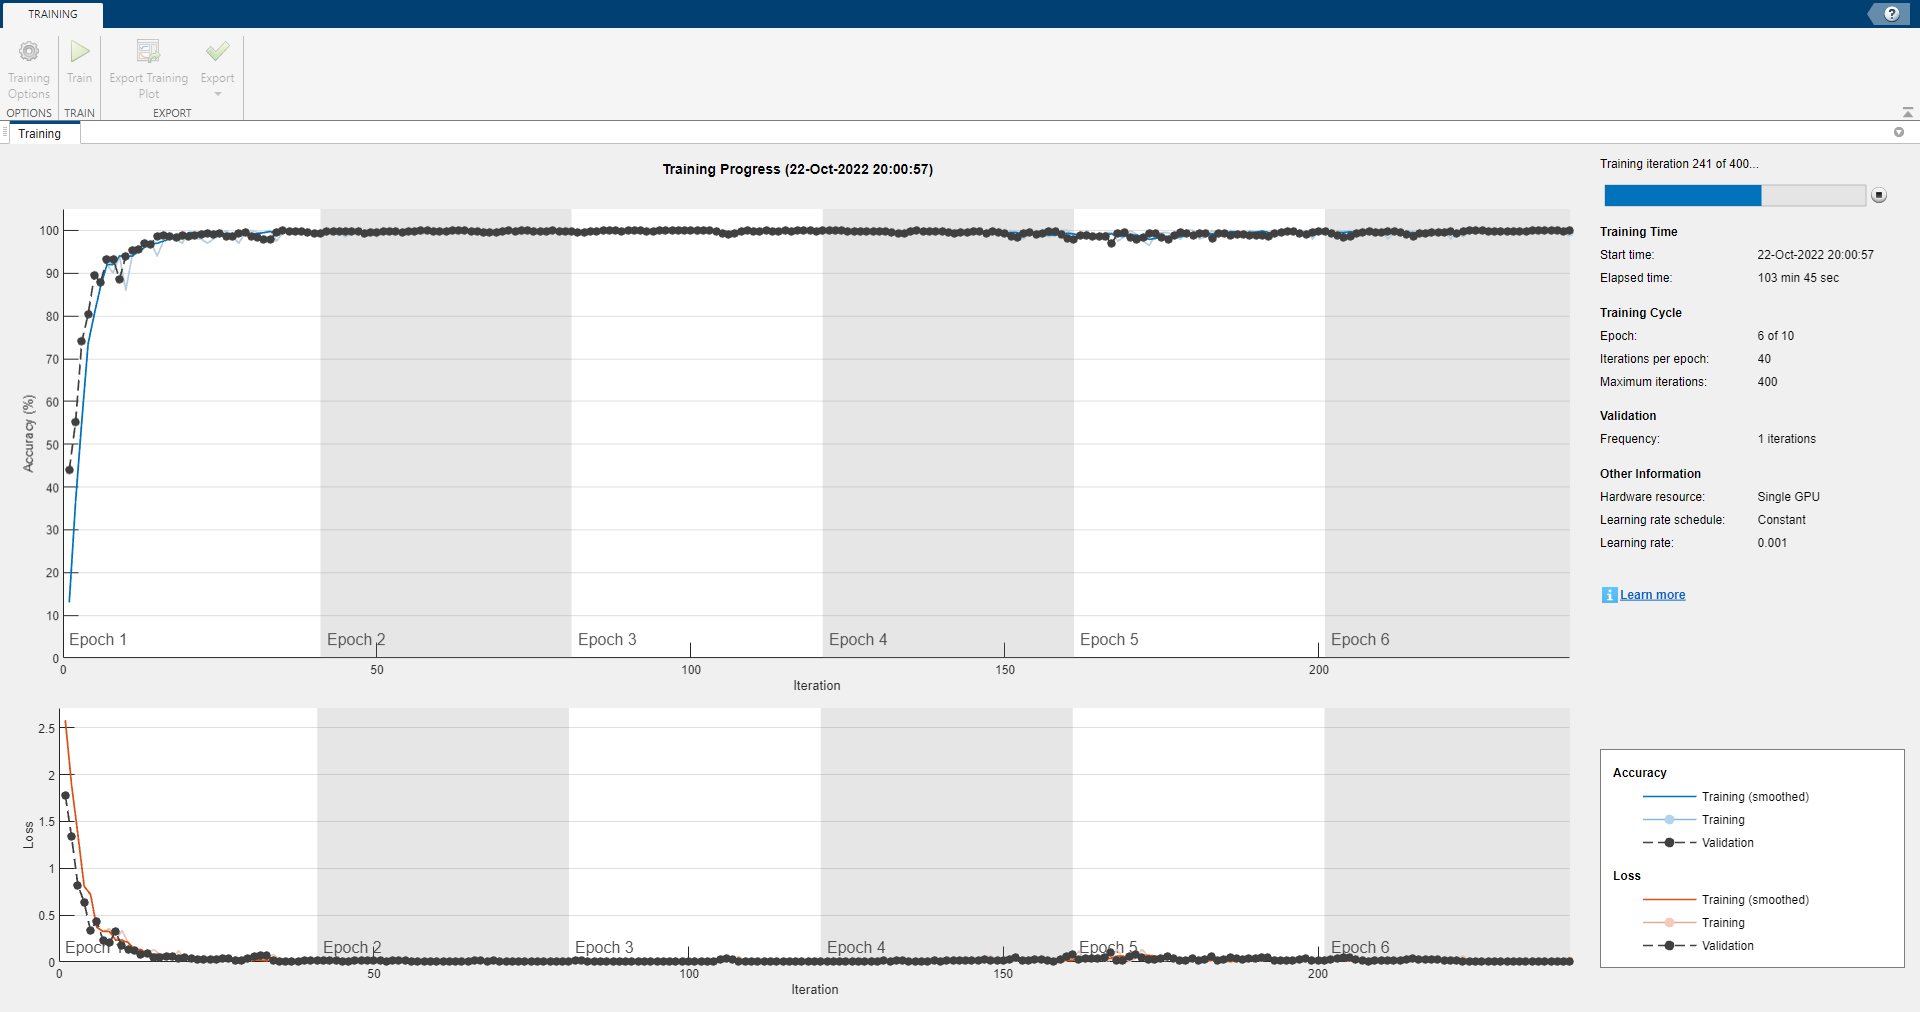

Por lo cual por la poca cantidad de clases que se tienen (10) se podría decir que una o máximo dos épocas estará listo el entrenamiento.

Para las características de este entrenamiento, se tuvo 10 épocas:

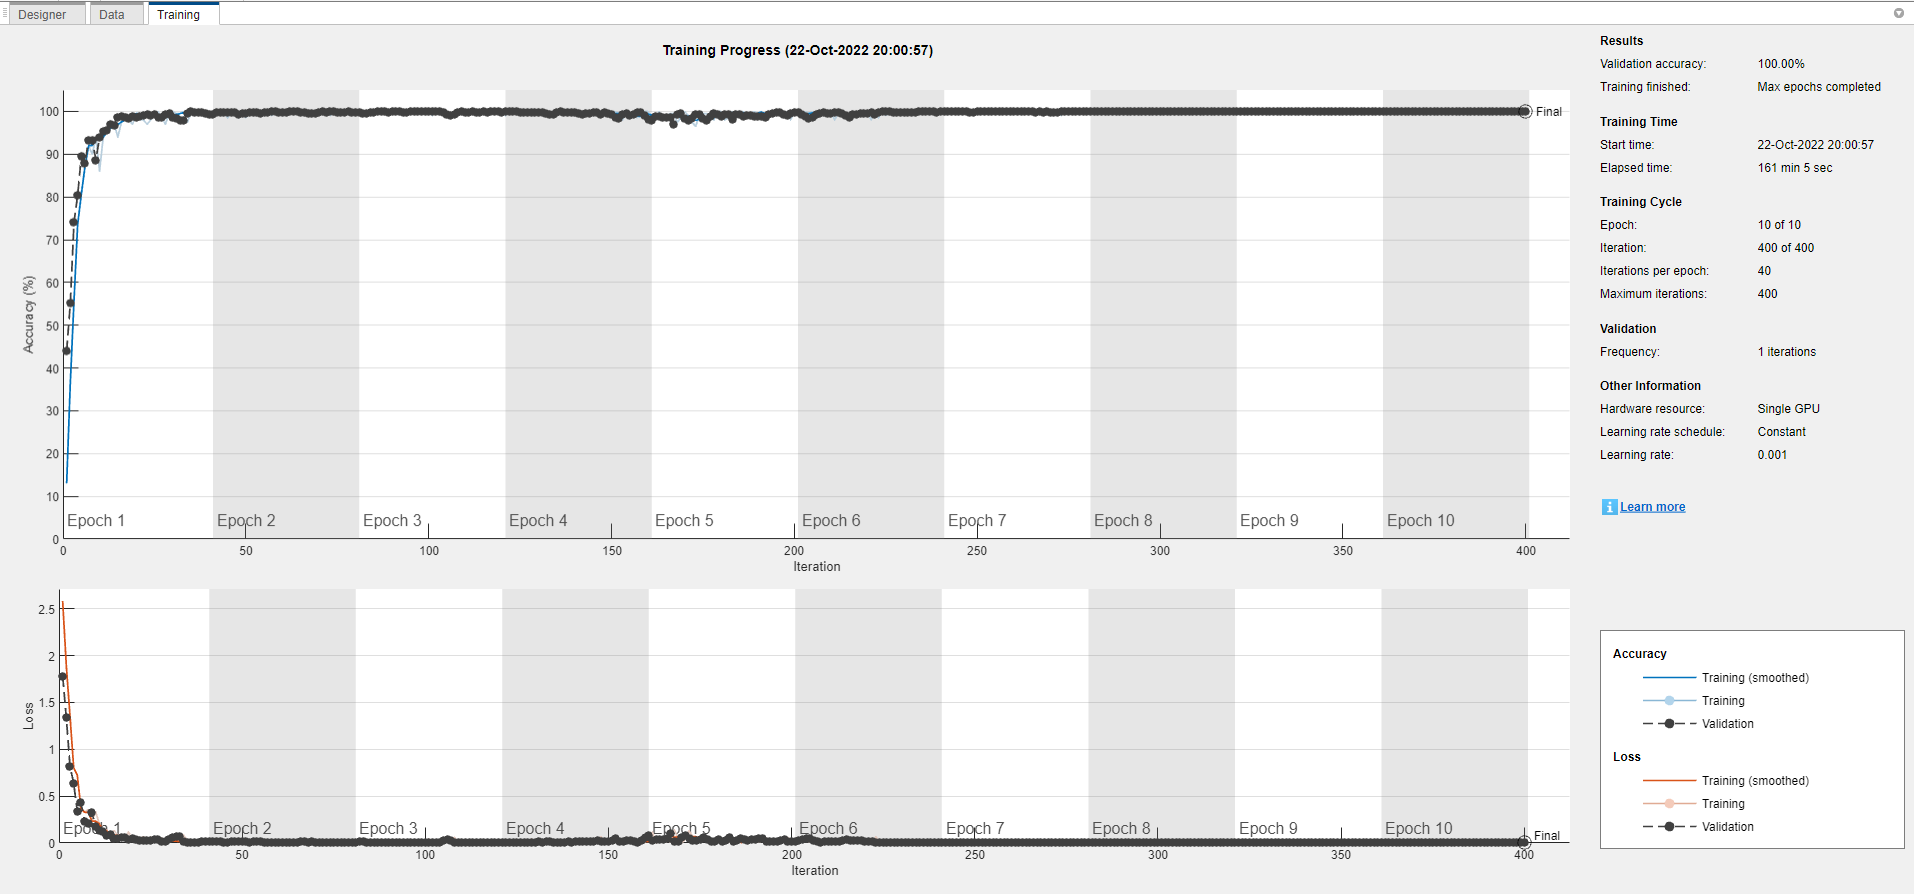

Se puede concluir de acá que con este entrenamiento en menos de dos épocas ya hubiera estado listo con las características que se definió, se ve que la precisión está cerca del 100% y la función de pérdida muy cerca del cero de acuerdo a la escala de las gráficas.

Ahora se procederá a colocar una tasa de aprendizaje de 0.01 con 3 épocas, el resultado se puede apreciar en la siguiente imagen

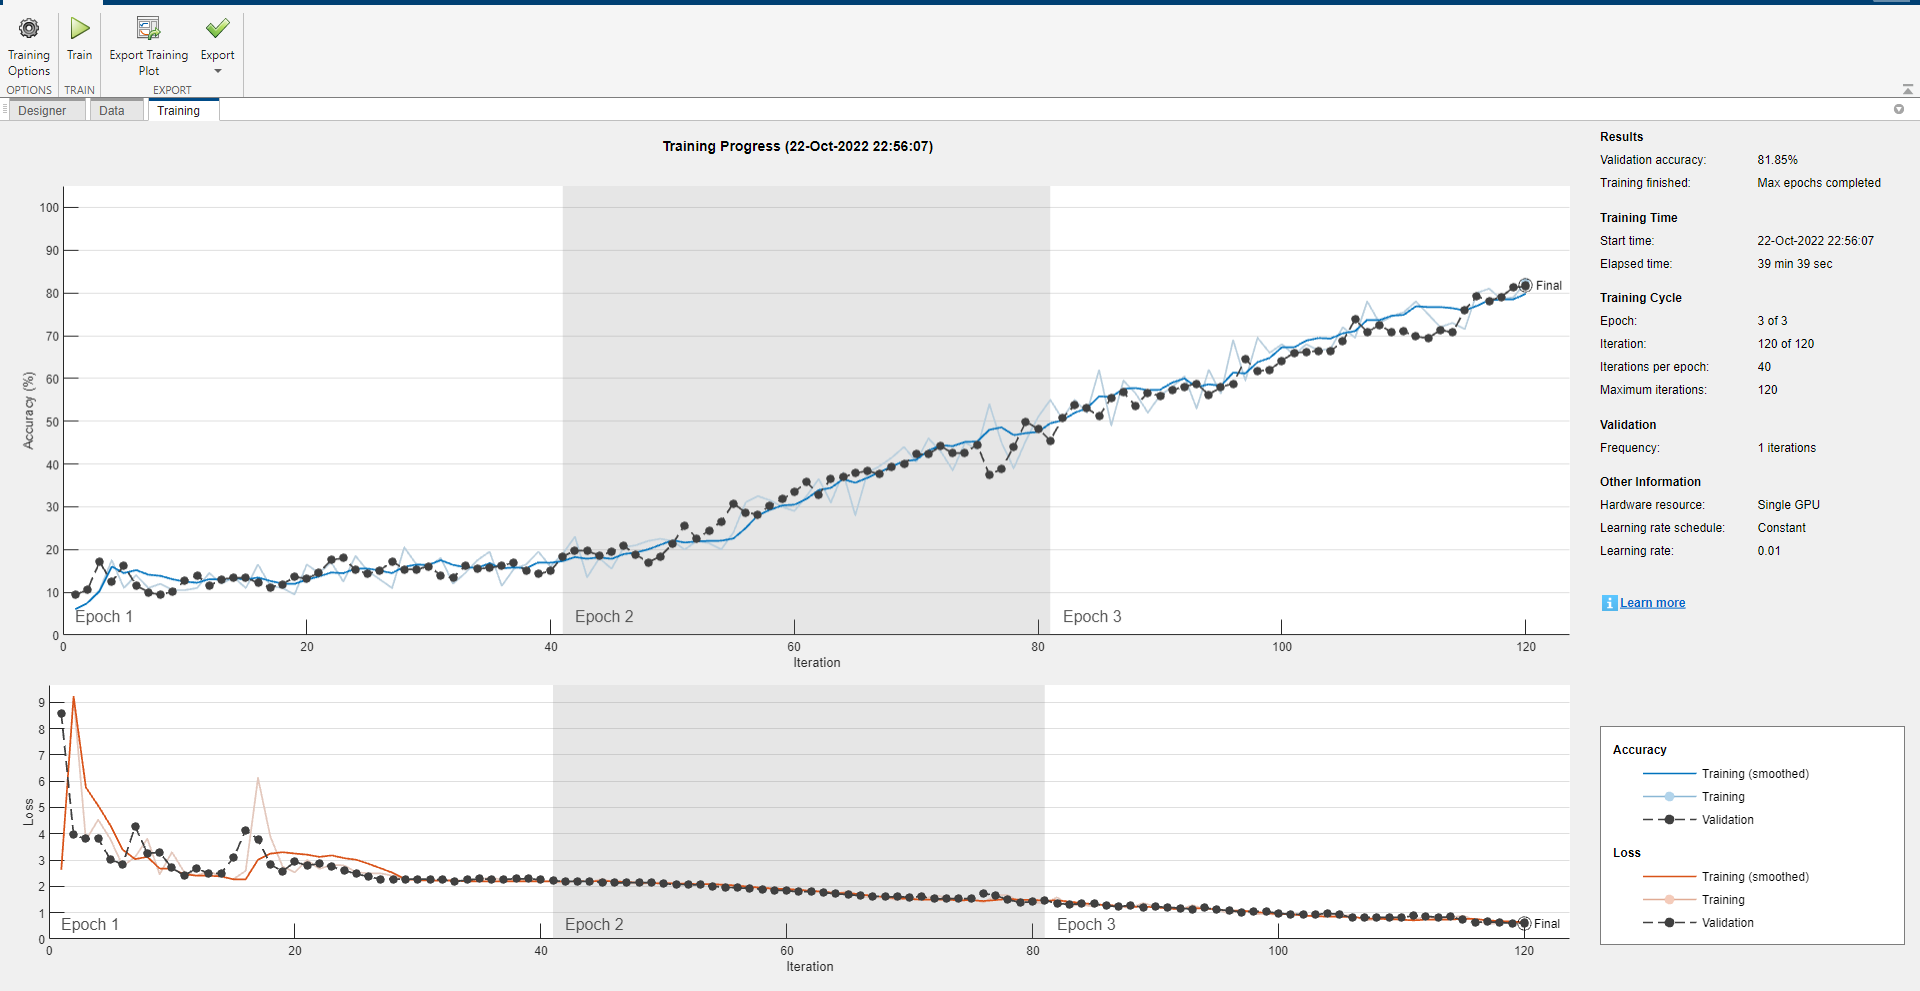

Para este entrenamiento se puede ver que la función de pérdida puede seguir bajando, y la precisión seguir subiendo (aunque no son una proporcional a la otra, sí son consecuencia), se propone hacer el siguiente con el doble de épocas para verificar hasta donde llega y si ya entra en una medida estacionaria, se cambiará el número de épocas a 6.

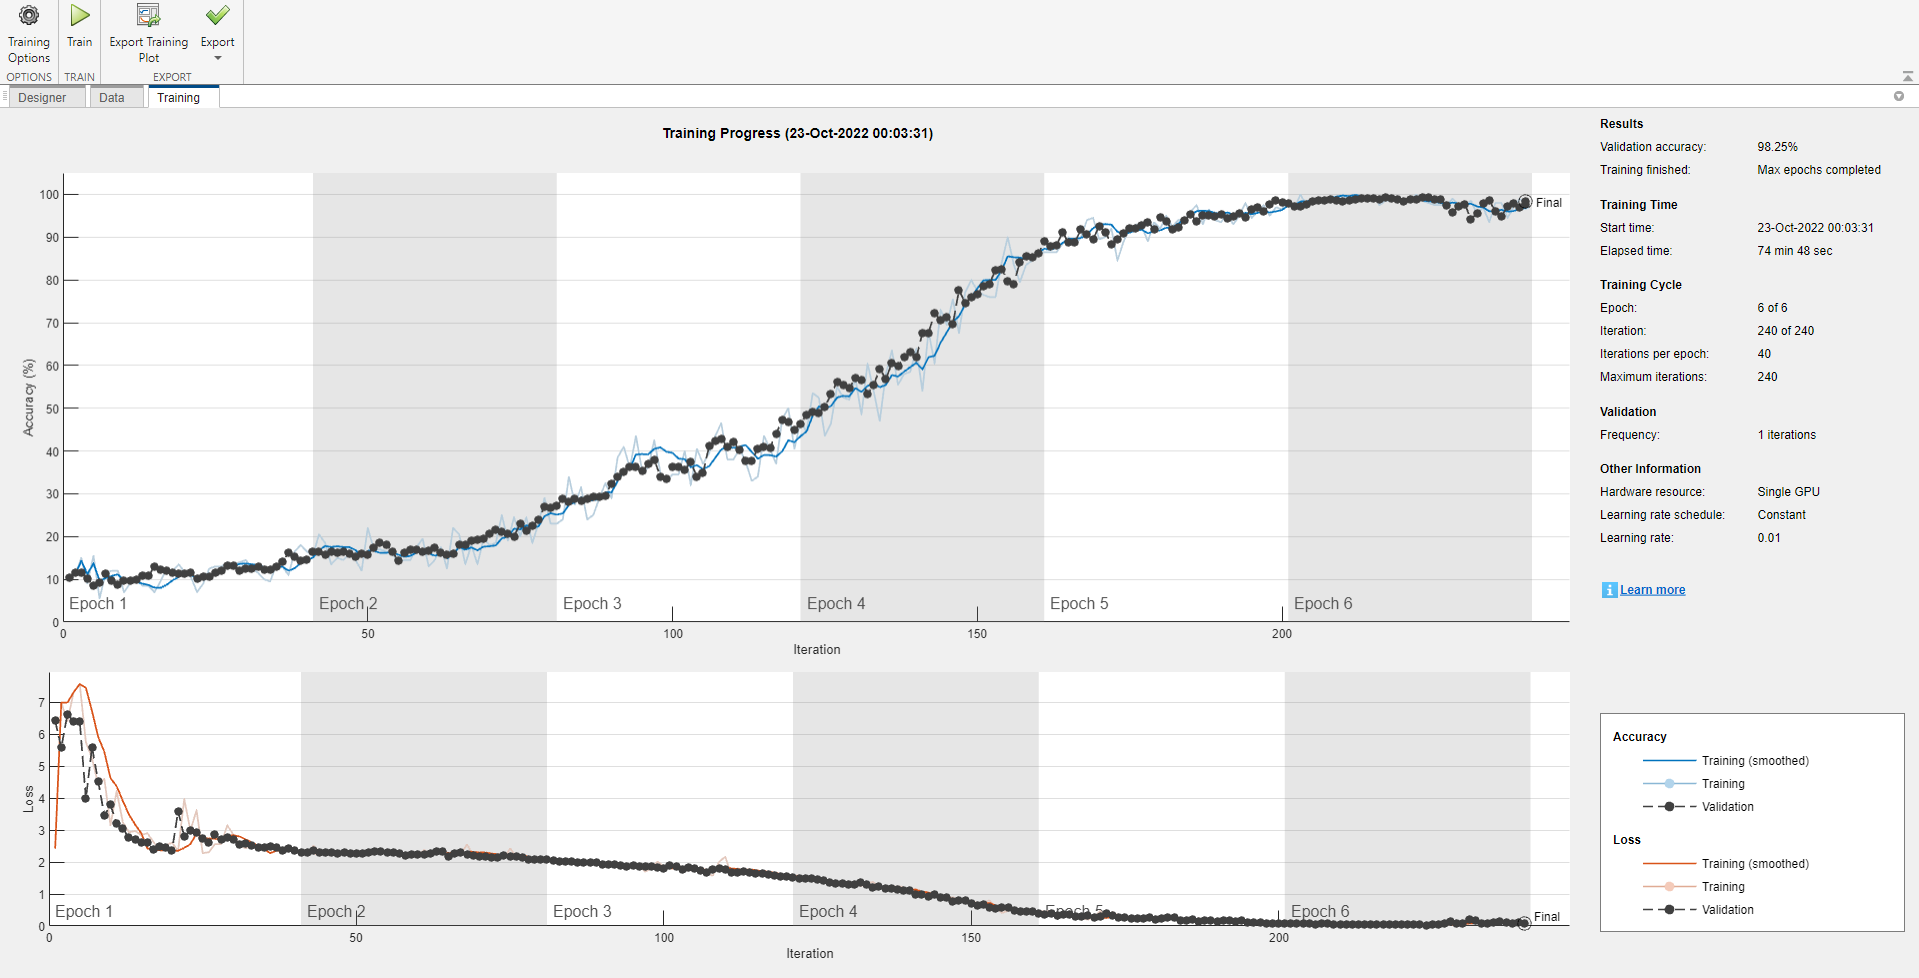

Acá se puede ver que para la tasa de aprendizaje propuesta, la gráfica entra en un estado "estacionario" a partir de un cuarto de la época 5, en el cual alcanza una precisión cercana al 100% con una función de pérdida bastante cercana al cero.

Como ya se vió una tasa de aprendizaje pequeña 1x10^-3 y una 10 veces más grande, se procederá a usar la que mejor se comportó reduciendo el número de épocas y se reducirá el batch size una cuarta parte a ver el resultado. El experimento inicial se hará con 10 épocas.

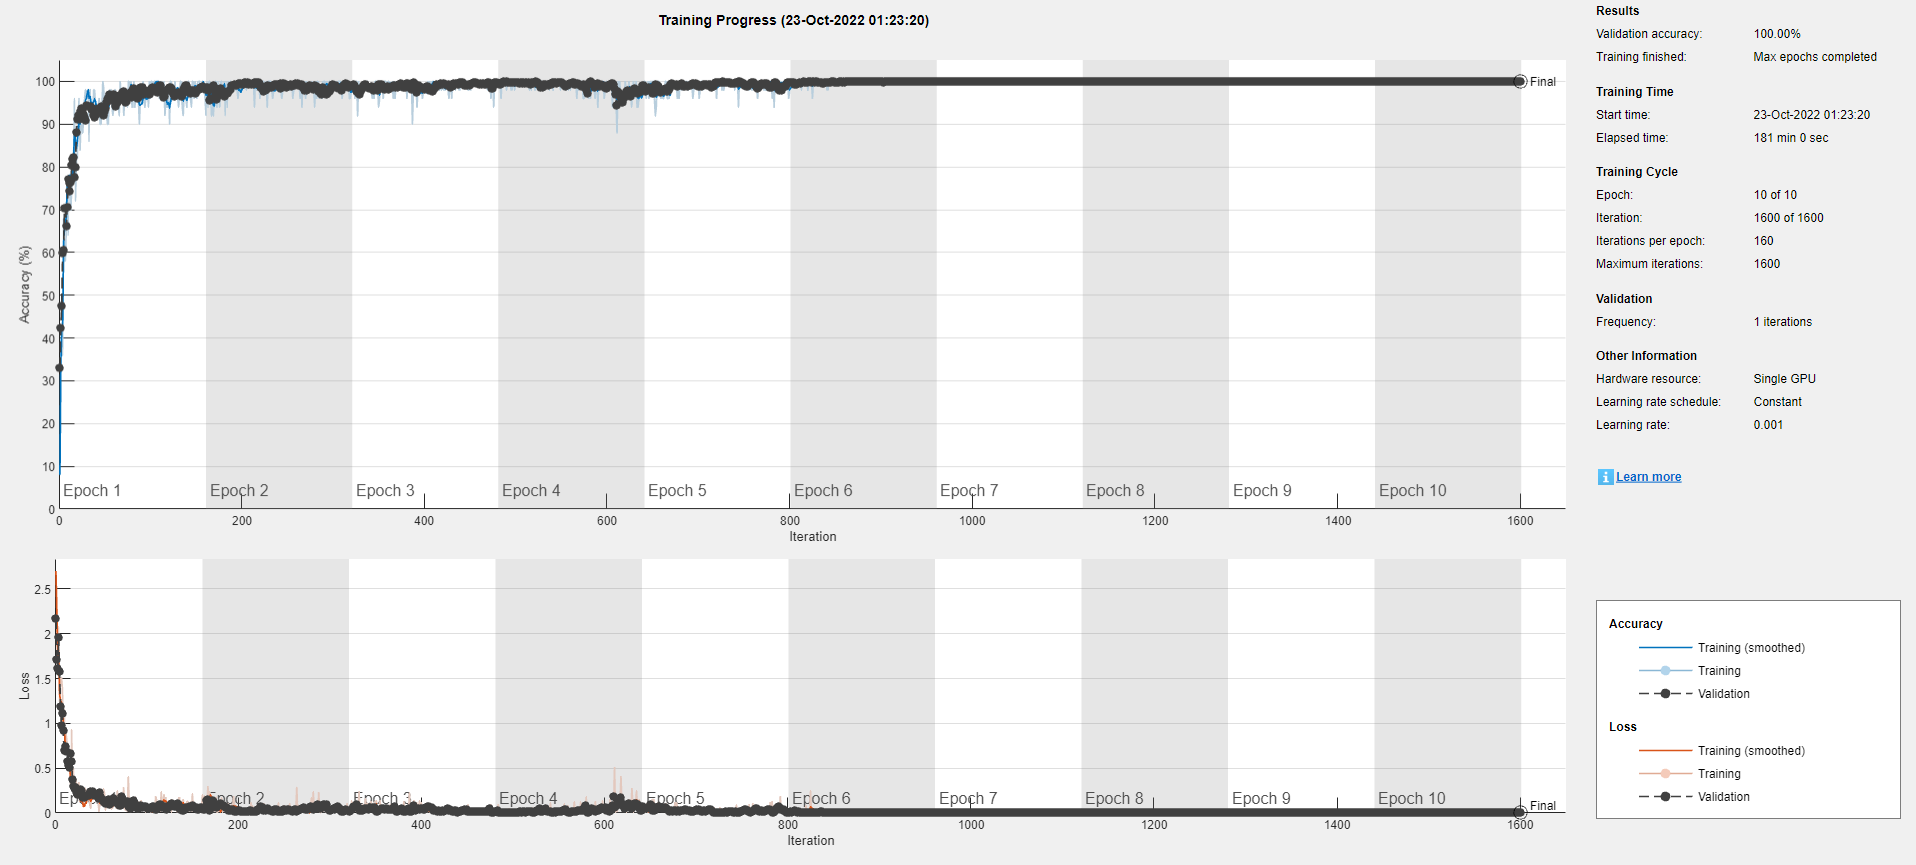

Con esto se puede concluir que la tasa de 0.001 es mucho mejor que la de 0.01, además de que reducir el batch size reduce el ruido en la función de pérdida y en el accuracy comparado con el resto, para hacer el último experimento con el batchsize se dejará de 1 durante 3 épocas con la misma tasa de aprendizaje.

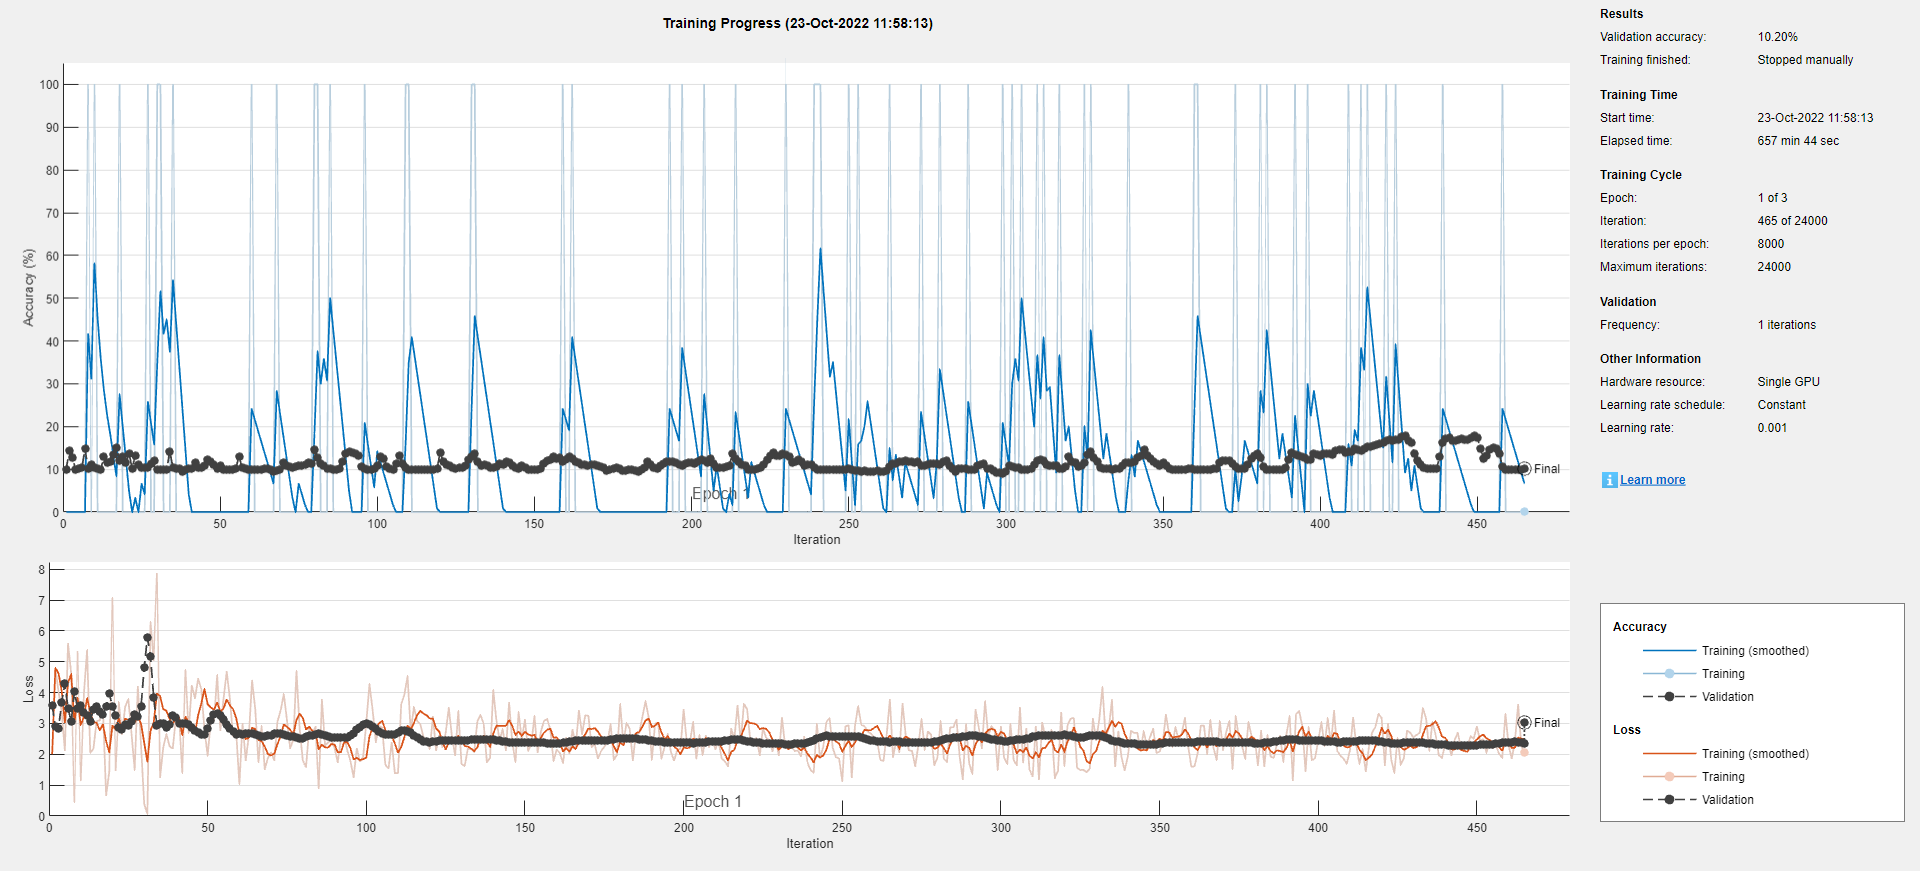

A pesar de estar en una GPU con cerca de 3500 núcleos CUDA, al tener un batch size de 1 se ha demorado más de 600 minutos en siquiera terminar una época, la ventaja de tener un batch size pequeño es no llenar tanto la memoria RAM de los dispositivos, sin embargo se puede ver que se demora MUCHO más de lo que se espera.

# **GoogleNet**

**Esta red hace uso de lo que ellos mismos definen como bloques de inception**

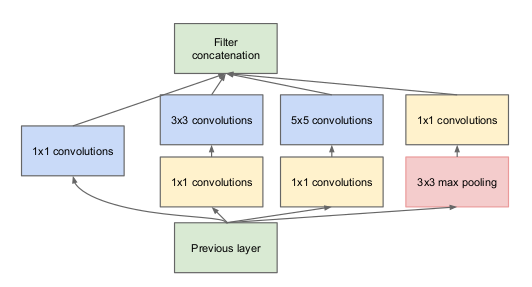

Para esta serie de experimentos lo que se variará es la tasa de aprendizaje y el batch size junto con el número de épocas, para ver qué tanto varía.

Al igual que en el anterior, el entrenamiento primero se hará con una tasa de aprendizaje de 0.001 y 10 épocas, sólo que esta vez se bajará el batchsize a 100.

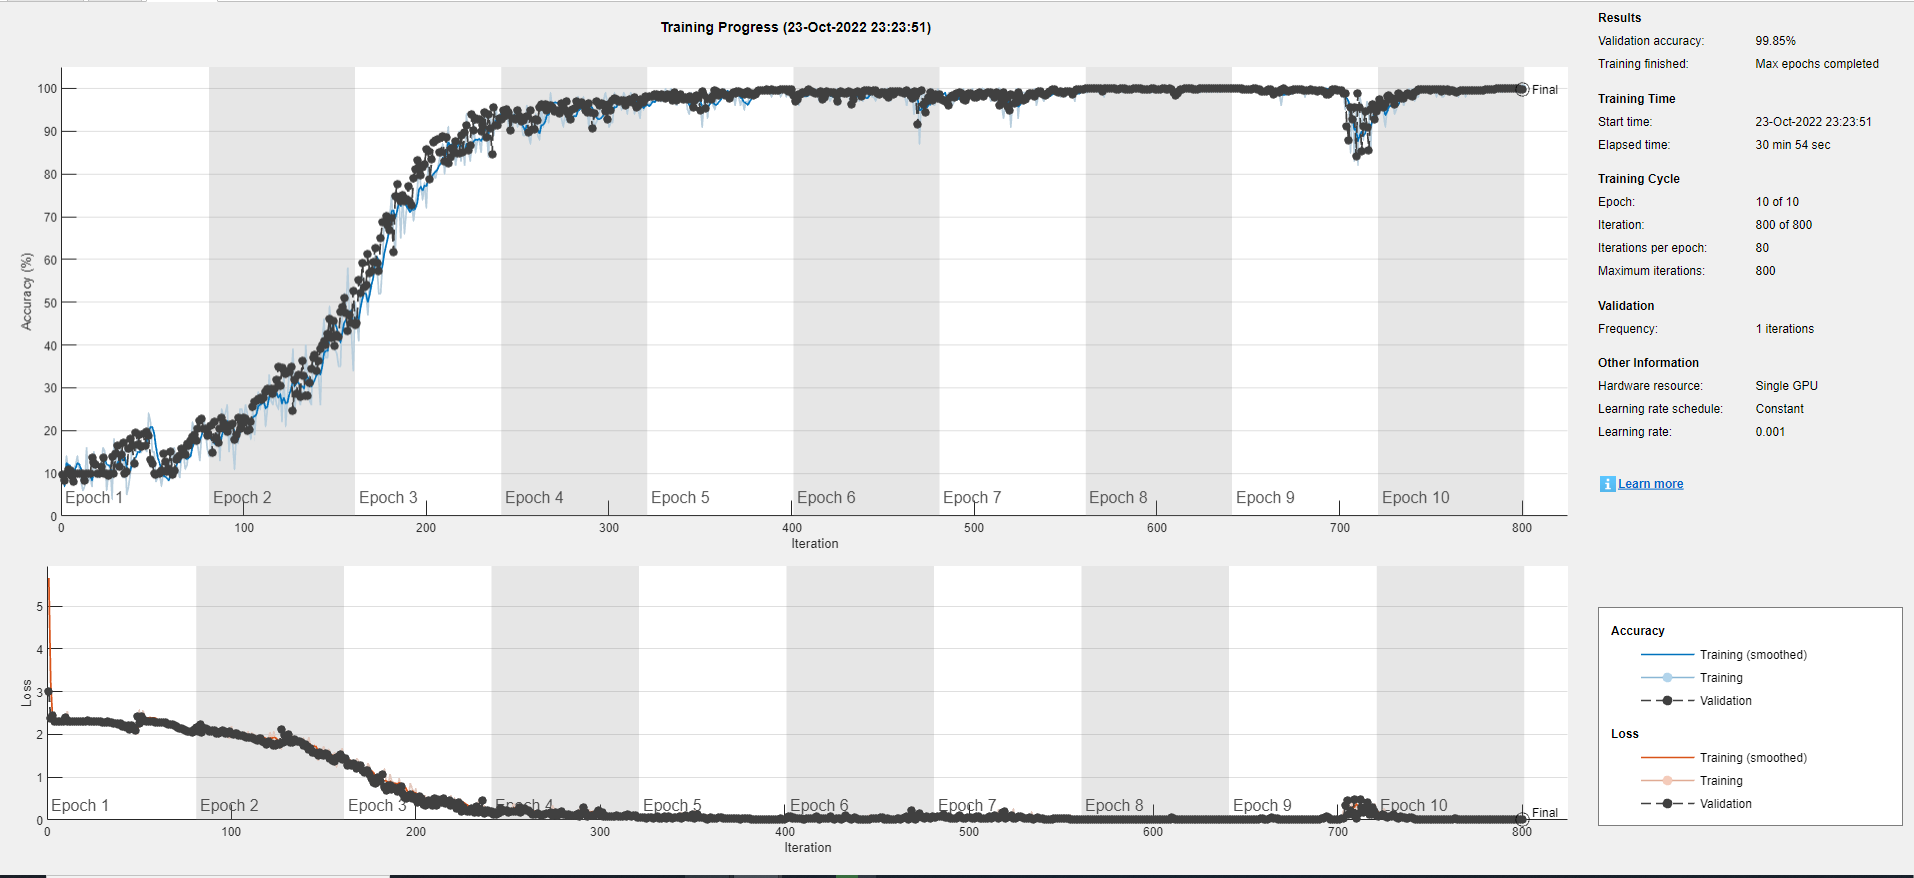

Se puede ver que al final tanto la precisión como la función de pérdida tuvieron un pequeño ruido, esto se pudo haber evitado poniendo un EarlyStopping cuando la función de pérdida por ejemplo dejara de variar décimas o centésimas de la misma, se llegó a una precisión buena en validación y entrenamiento, además de esto no hubo overfitting.

Finalmente como vimos que se puede observar el comportamiento, se procederá a dejar la misma cantidad de épocas, el mismo batch size con una tasa de aprendizaje de 0.01

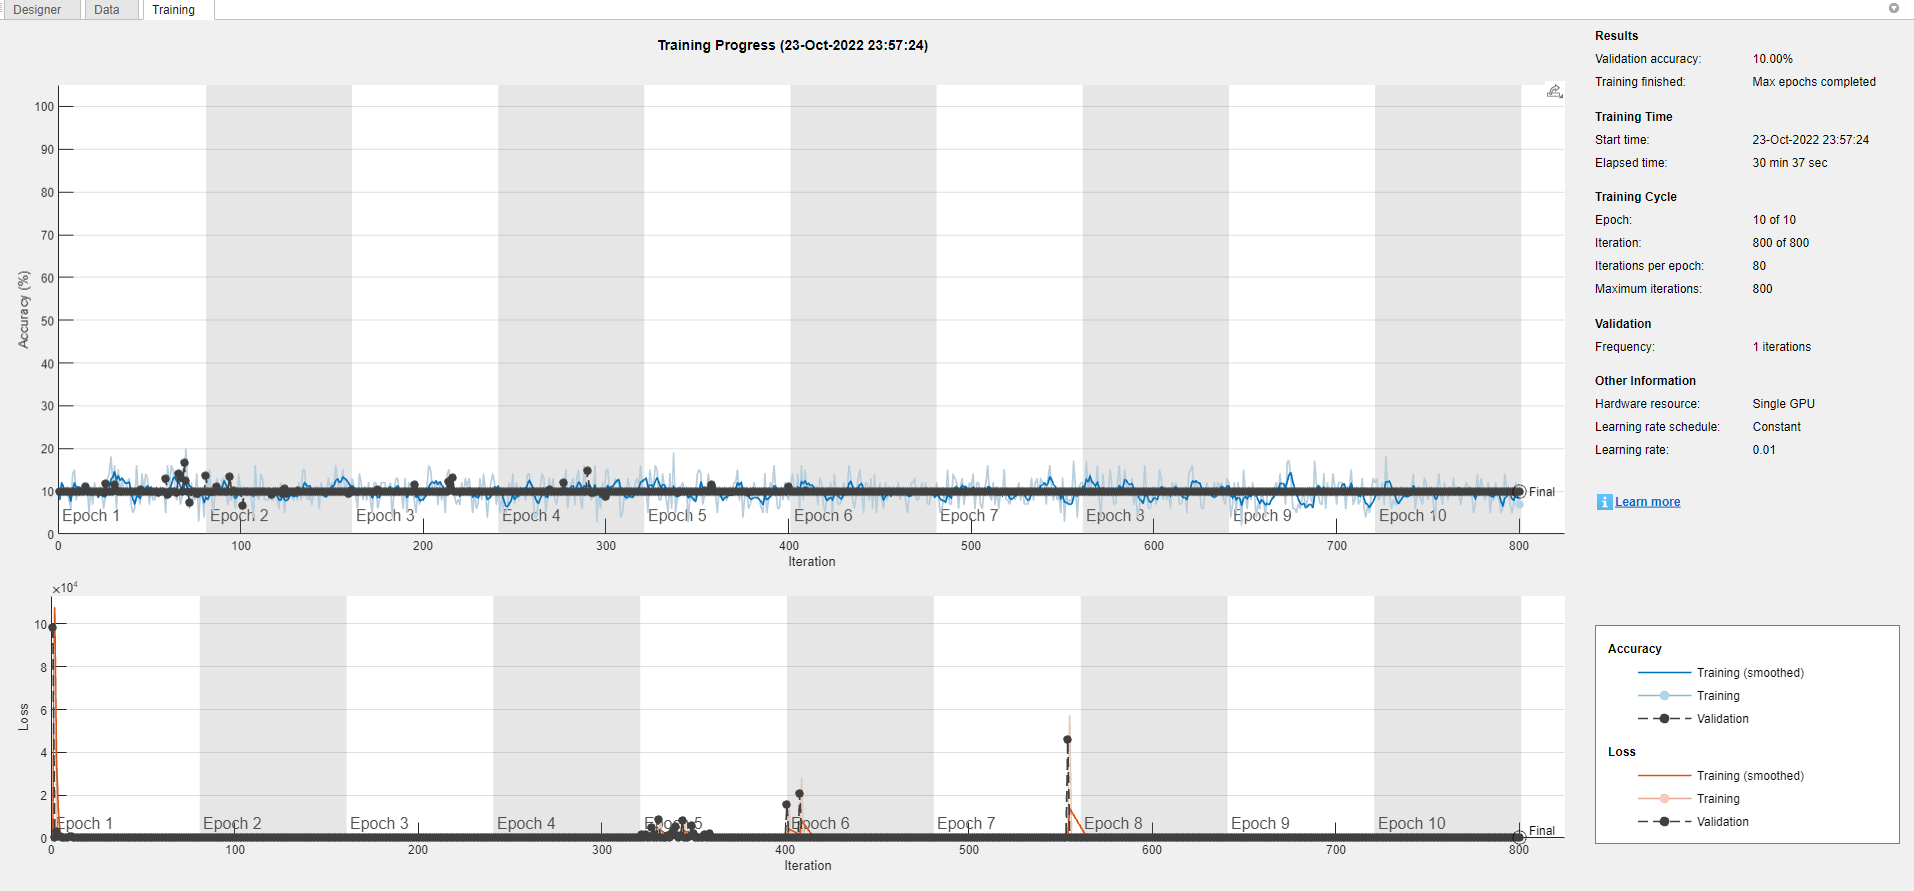

Acá se puede ver que el resultado del entrenamiento fue desastroso, por lo cual estos parámetros de entrenamiento no se recomiendan.

# Conclusiones

- La cantidad de parámetros entrenables de la red va a hacer que esta requiera más o menos información para entrenarse, como se tienen millones de parámetros se deben tener una cantidad de datos bastante grande, podría buscarse alguna relación entre la cantidad de parámetros y el número de datos necesarios para lograr un resultado satisfactorio.

- El desempeño de ResNet-50 fue mucho mejor para una tasa de aprendizaje más grande.

- El batch size demasiado grande consume mucha memoria volatil RAM de los recursos.

- El batch size demasiado pequeño hace que el entrenamiento demore muchísimo más y no sea fructífero tampoco.

- Dependiendo de la red la tasa de aprendizaje puede ser mejor si es más grande o más pequeña, todo depende de la arquitectura, por la cual se sugiere experimentar.

- Se descartaron los WeightLearningRate y el BiasLearningRate para que la red aprendiera todos los parámetros entrenables con la misma tasa de aprendizaje.